close all
clear all
clc        

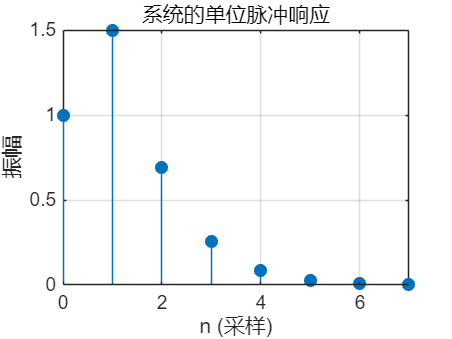

num=[1,1];
den=[1,-0.5,0.06];
figure(1)
impz(num,den);
title('系统的单位脉冲响应');
grid on;

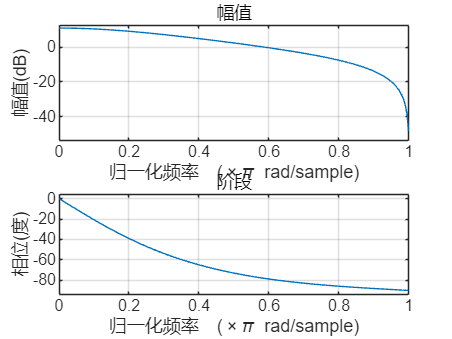

figure(2)
freqz(num,den);
grid on;

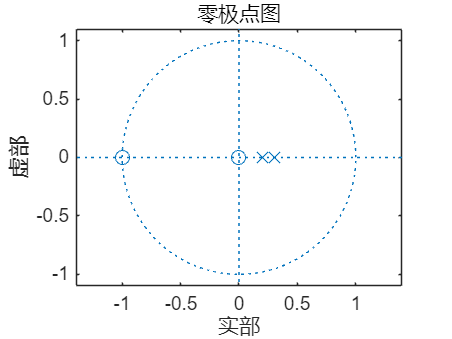

figure(3);
zplane(num,den);

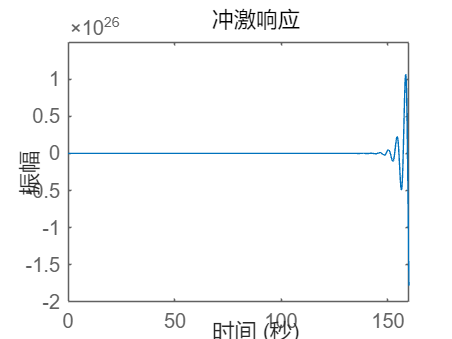

num=1;
den=[1,0,2,2];
impulse(num,den);

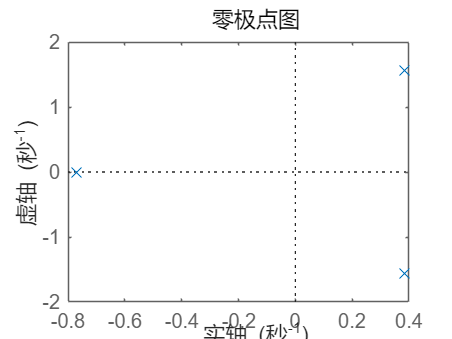

pzmap(tf(num,den));

a = [1,0,2,2];
N = length(a);
M = ceil(N/2);
R = zeros(N, M);
R(1,:)= [a(1:2:end) zeros(1,M-length(a(1:2:end)))];
R(2,:)= [a(2:2:end) zeros(1, M - length(a(2:2:end)))];
for n = 3:N
    if R(n-1,1)==0
        R(n-1,1)=eps
    end
    for m = 1:M-1
        R(n, m) = (R(n-2, m+1) * R(n-1, 1) - R(n-2, 1) * R(n-1, m+1)) / R(n-1, 1);
    end
end

R =     1.0000    2.0000
    0.0000    2.0000
         0         0
         0         0


disp('Routh阵列：');

Routh阵列：


disp(R);

   1.0e+15 *

    0.0000    0.0000
    0.0000    0.0000
   -9.0072         0
    0.0000         0



if all(R(:,1) > 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定


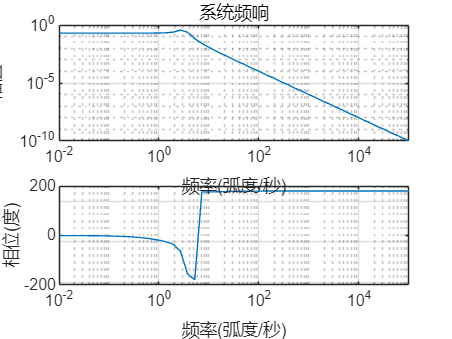

num = [0,1,4];
den = [1,3,12,20];
t = 0:0.01:5;
x = sin(0.5*pi*t);
figure(4)
w=logspace(-2,5);
freqs(num,den,w);
title('系统频响');
grid on;

[a,b,c,d]=tf2ss(num,den);
sys=ss(a,b,c,d);
A=[1,-a(1,1),-a(1,2);c(1),c(2),0;0,c(1),c(2)];
R=A\[-6,0,1]';
disp(R) %初始状态

   -18
     0
     1



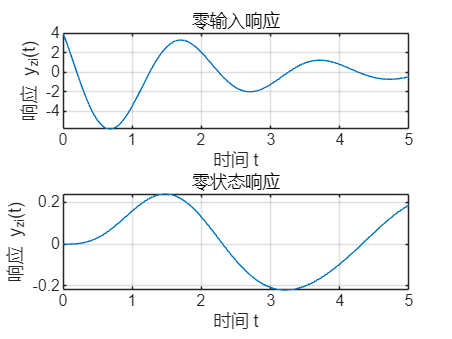

figure(5)
subplot(2,1,1)
yinitial = initial(sys,R(1:3),t);
plot(t,yinitial);
title('零输入响应');
xlabel('时间 t');
ylabel('响应 y_{zi}(t)');
grid on;
subplot(2,1,2)
yzerostate = lsim(num,den,x,t);
plot(t,yzerostate);
title('零状态响应');
xlabel('时间 t');
ylabel('响应 y_{zi}(t)');
grid on;

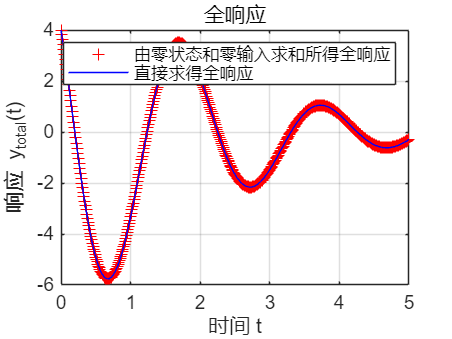

figure(6)
yfull = yinitial + yzerostate;
plot(t,yfull,'r+')
hold on;
yfull1 = lsim(sys,x,t,R(1:3));
plot(t,yfull1,'b-')
title('全响应');
xlabel('时间 t');
ylabel('响应 y_{total}(t)');
grid on;
hold off;
legend('由零状态和零输入求和所得全响应','直接求得全响应');

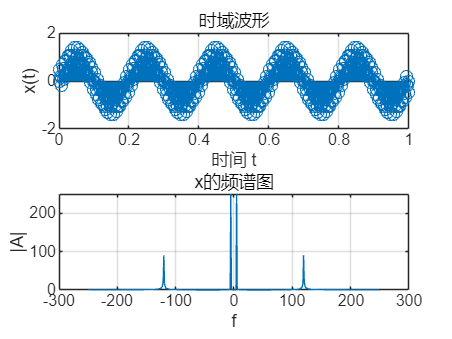

t=0:0.002:1;
f1=5;
f2=120;
x=sin(2*pi*f1*t)+0.4*sin(2*pi*f2*t);
figure(7);
subplot(2,1,1);
stem(t,x);
xlabel('时间 t');
ylabel('x(t)');
title('时域波形');
grid on;
subplot(2,1,2);
L=length(t);
w=(-L/2:L/2-1)/L/0.002;
ft_x=fftshift(fft(x,L));
plot(w,abs(ft_x));
xlabel('f');
ylabel('|A|');
title('x的频谱图');
grid on;

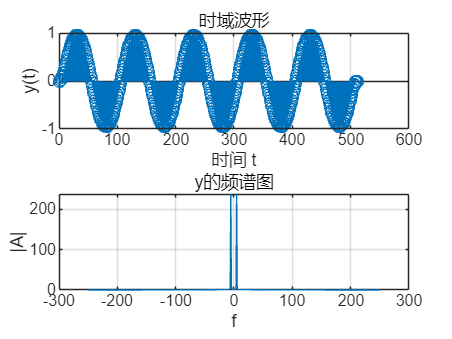


h=[0.008  0.02  0.06  0.12  0.17  0.2  0.17  0.12  0.06  0.02  0.008];
y=conv(h,x);
figure(8);
subplot(2,1,1);
stem(y);
xlabel('时间 t');
ylabel('y(t)');
title('时域波形');
grid on;
subplot(2,1,2);
L=length(t);
w=(-L/2:L/2-1)/L/0.002;
ft_x=fftshift(fft(y,L));
plot(w,abs(ft_x));
xlabel('f');
ylabel('|A|');
title('y的频谱图');
grid on;

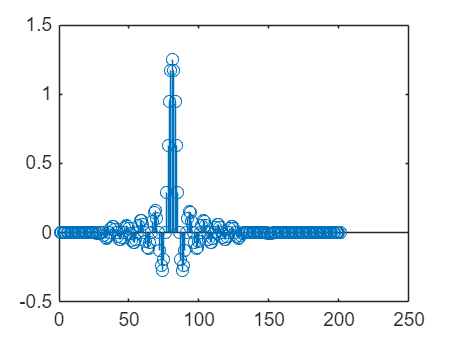

n=0:100;
L=length(n);
w=(-L/2:L/2-1)/L;
x=sinc(0.2*(n-50)).*cos(2*n);
s=cos(2*n);
h=sinc(0.4*(n-30));
figure(9);
y=conv(x.*s,h);
stem(y);

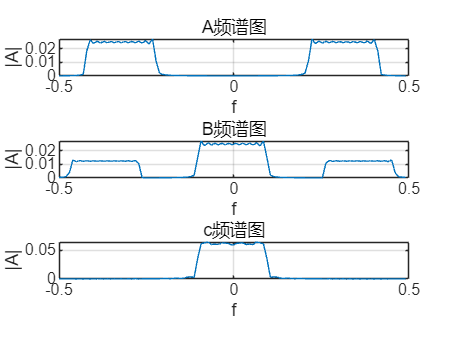


figure(10);
subplot(3,1,1);
f=fft(x,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('A频谱图');
grid on;

subplot(3,1,2);
f=fft(x.*s,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('B频谱图');
grid on;

subplot(3,1,3);
f=fft(y,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('c频谱图');
grid on;